angle=input('Enter launch angle(deg) = ');
v0=input('Enter initial velocity(m/s) = ');
g=9.81;

theta=deg2rad(angle);

t_flight = (2*v0*sin(theta))/g;
Max_Height= (v0 * sin(theta))^2 / (2*g);
Range=(v0^2*sin(2*theta))/g;

t=linspace(0,t_flight,100)

t =          0    0.0291    0.0582    0.0874    0.1165    0.1456    0.1747    0.2039    0.2330    0.2621    0.2912    0.3204    0.3495    0.3786    0.4077    0.4368    0.4660    0.4951    0.5242    0.5533    0.5825    0.6116    0.6407    0.6698    0.6990    0.7281    0.7572    0.7863    0.8155    0.8446    0.8737    0.9028    0.9319    0.9611    0.9902    1.0193    1.0484    1.0776    1.1067    1.1358    1.1649    1.1941    1.2232    1.2523    1.2814    1.3105    1.3397    1.3688    1.3979    1.4270


x=v0 * cos(theta) * t;
y=v0 * sin(theta) * t - 0.5 * g * t.^2;
choice = menu('What do you want to calculate', ...
    'Time of flight', 'Maximum height', 'Maximum range', 'All');

if choice==1
    fprintf('Time of flight(s): %.4f', t_flight)
elseif choice==2
    fprintf('Maximum Height(m): %.4f', Max_Height)
elseif choice==3
    fprintf('Maximum Range(m): %.4f', Range)
elseif choice==4
    fprintf('Time of flightm)(m): %.4f', t_flight)
    fprintf('Maximum Heigh9t(m): %.4f', Max_Height)
    fprintf('Maximum Range(m): %.4f', Range)
end

Time of flightm)(m): 2.8832

Maximum Heigh9t(m): 10.1937

Maximum Range(m): 40.7747

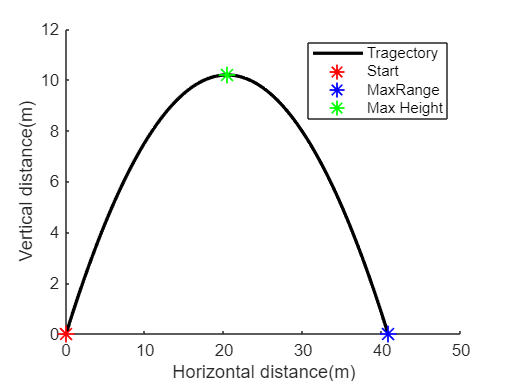


tpeak=t_flight/2;
xpeak=v0 * cos(theta) * tpeak;
ypeak=v0 * sin(theta) * tpeak - 0.5 * g * tpeak.^2;

hold on
plot(x,y, 'k', 'LineWidth', 2)
plot(0,0, 'r*' ,'MarkerSize', 10, 'LineWidth', 1)
plot(Range,0 , 'b*', 'MarkerSize', 10, 'LineWidth', 1)
plot(xpeak,ypeak , 'g*', 'MarkerSize', 10, 'LineWidth', 1)
xlabel('Horizontal distance(m)')
ylabel('Vertical distance(m)')
legend('Tragectory', 'Start', 'MaxRange', 'Max Height')


download=menu('Do you want to save the graph', ...
    'Yes', 'No')

download = 2


if download==1
    filename=input('Enter filename: ', 's')
    format=menu('Pdf or Picture', ...
        'PDF', 'JPG', 'PNG');
    
    if format==1
        exportgraphics(gcf, [filename, '.pdf']);
    elseif format==2
        saveas(gcf, [filename, '.jpg']);
    elseif format==3
        saveas(gcf, [filename, '.png']);
    end
else
    disp('Graph not saved')
end

Graph not saved
